## Data sampling for ID

### trim data

start_time = duration('00:02:16.148000');
end_time = duration('00:02:16.14850');

% Create a timerange object
ts_range = timerange(start_time, end_time);

% Index both pitch_in and elevator using the rows subscript
elevator_trim = pitch_in.pitch_in(ts_range,:)

elevator_trim = 0.1368

throttle_trim = throttle_in.throttle_in(ts_range,:)

throttle_trim = 0.3304

rpm_trim = rpm_m.rpm_m(ts_range,:)

rpm_trim = 36589

airspeed_trim = ind_airspeed.indicated_airspeed(ts_range,:)

airspeed_trim = single
14.7282

alt_trim = alt.alt(ts_range,:)

alt_trim = single
235.1120

pitch_rate_trim = q.q(ts_range,:)

pitch_rate_trim = 0.7505

alpha_trim = alpha.alpha(ts_range,:)

alpha_trim = single
0.9369

### step input

t_start = duration('00:02:15.223879');
t_end_s = duration('00:02:21.233258');
t_end_p = duration('00:02:30.379288');

% sampling the short period inputs - 5 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_s);
rpm_s_step = rpm_m.rpm_m(ts_range,:) - rpm_trim;
throttle_s_step = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_s_step = pitch_in.pitch_in(ts_range,:) - elevator_trim;
q_s_step = q.q(ts_range,:); 
aoa_s_step = alpha.alpha(ts_range,:);

%smapling phugoid inputs - atleast 10 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_p);
rpm_p_step = rpm_m.rpm_m(ts_range,:) - rpm_trim;
throttle_p_step = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_p_step = pitch_in.pitch_in(ts_range,:) - elevator_trim;
vel_p_step = ind_airspeed.indicated_airspeed(ts_range,:); 
alt_p_step = alt.alt(ts_range,:);

### doublet input

t_start = duration('00:02:56.829399');
t_end_s = duration('00:03:05.306886');
t_end_p = duration('00:03:09.179269');
% sampling the short period inputs - 5 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_s);
rpm_s_doublet = rpm_m.rpm_m(ts_range,:) - rpm_trim;
throttle_s_doublet = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_s_doublet = pitch_in.pitch_in(ts_range,:) - elevator_trim;
q_s_doublet = q.q(ts_range,:); 
aoa_s_doublet = alpha.alpha(ts_range,:);

%smapling phugoid inputs - atleast 10 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_p);
rpm_p_doublet = rpm_m.rpm_m(ts_range,:) - rpm_trim;
throttle_p_doublet = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_p_doublet = pitch_in.pitch_in(ts_range,:) - elevator_trim;
vel_p_doublet = ind_airspeed.indicated_airspeed(ts_range,:); 
alt_p_doublet = alt.alt(ts_range,:);

### sine sweep input

t_start = duration('00:03:42.946086');
t_end_s = duration('00:03:59.769274');
t_end_p = duration('00:03:59.769274');
% sampling the short period inputs - 5 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_s);
rpm_s_sine = rpm_m.rpm_m(ts_range,:) - rpm_trim;
throttle_s_sine = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_s_sine = pitch_in.pitch_in(ts_range,:) - elevator_trim;
q_s_sine = q.q(ts_range,:); 
aoa_s_sine = alpha.alpha(ts_range,:);

%smapling phugoid inputs - atleast 10 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_p);
rpm_p_sine = rpm_m.rpm_m(ts_range,:) - rpm_trim;
throttle_p_sine = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_p_sine = pitch_in.pitch_in(ts_range,:) - elevator_trim;
vel_p_sine = ind_airspeed.indicated_airspeed(ts_range,:); 
alt_p_sine = alt.alt(ts_range,:);

## System ID script - step

iodelay = 0;
u1 = rpm_s_step;
u2 = elevator_s_step;
u3 = rpm_p_step;
u4 = elevator_p_step;
airspeed_trim = vel_p_step(1,1);
alt_trim = alt_p_step(1,1);
pitch_rate_trim = q_s_step(1,1);
alpha_trim = aoa_s_step(1,1);
y3 = q_s_step - pitch_rate_trim;
y1 = double(vel_p_step - airspeed_trim);
y4 = double(aoa_s_step - alpha_trim);
y5 = double(alt_p_step - alt_trim);

### MIMO identification - short period mode

u = [u1];
y = [y3];
np = [2];%[2 2; 2 2];
nz = [1]%[1 2; 1 1];

nz = 1

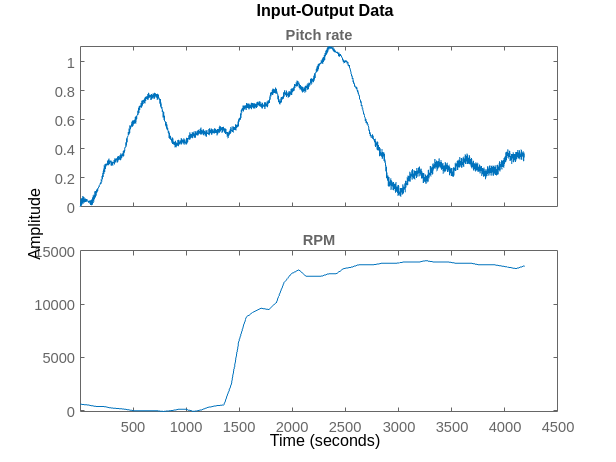

data = iddata(y,u);
set(data,'InputName',{'RPM'},'OutputName',{'Pitch rate'})
plot(data)

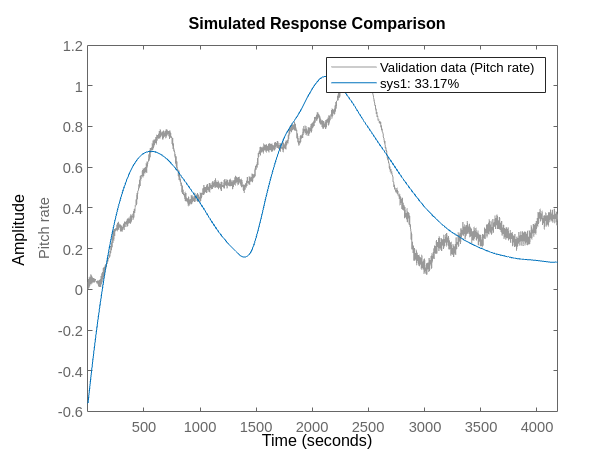

sys1= tfest(data,np,nz,iodelay);
compare(data,sys1)

### MIMO identification - Phugoid mode

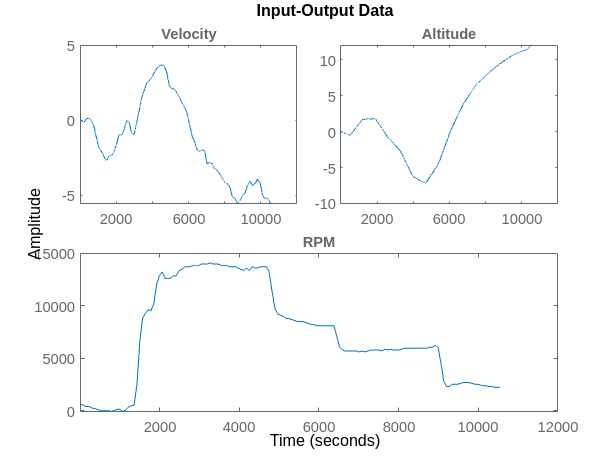

u = [u3];
y = [y1 y5];
np = [2;2];%[3 2; 3 3];
nz = [1;1];%[1 1; 2 2];
data = iddata(y,u);
set(data,'InputName',{'RPM'},'OutputName',{'Velocity', 'Altitude'}); %,'Evelator deflection'
plot(data)

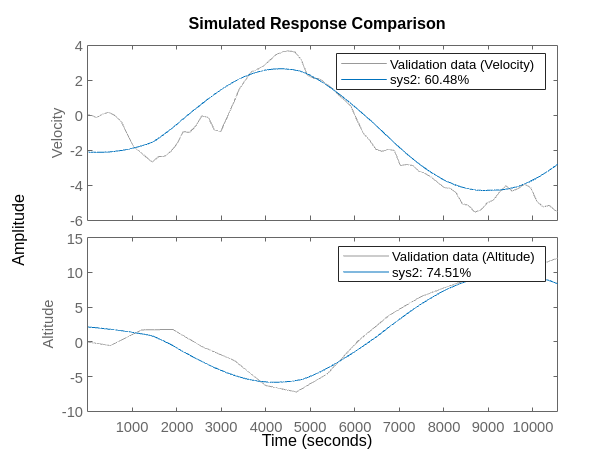

sys2= tfest(data,np,nz,iodelay);
compare(data,sys2)

### system identified

G1_tf = tf([sys1; sys2])  %Inputs-Throttle, evelator & outputs-Pitchrate, aoa, velocity, height

G1_tf =
 
  From input "RPM" to output...
                  4.676e-07 s + 1.023e-10
   Pitch rate:  ----------------------------
                s^2 + 0.003052 s + 6.571e-06
 
                 9.563e-08 s - 2.736e-11
   Velocity:  -----------------------------
              s^2 + 1.423e-05 s + 3.829e-07
 
                -2.158e-07 s + 3.738e-11
   Altitude:  -----------------------------
              s^2 + 2.896e-17 s + 3.073e-07
 
Continuous-time transfer function.



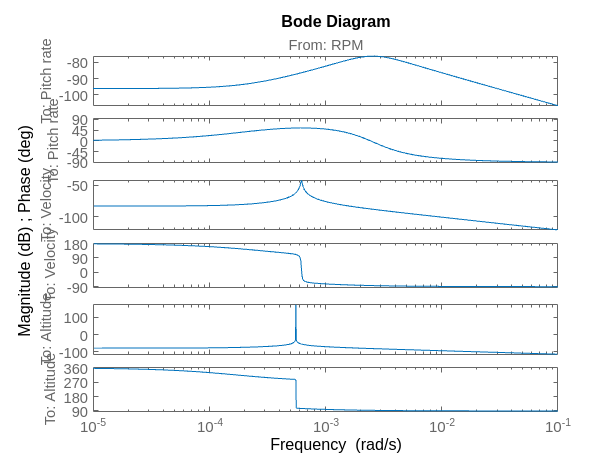

bode(G1_tf)

## System ID script - doublet

iodelay = 0;
u1 = rpm_s_doublet;
u2 = elevator_s_doublet;
u3 = rpm_p_doublet;
u4 = elevator_p_doublet;
airspeed_trim = vel_p_doublet(1,1);
alt_trim = alt_p_doublet(1,1);
pitch_rate_trim = q_s_doublet(1,1);
alpha_trim = aoa_s_doublet(1,1);
y1 = double(vel_p_doublet - airspeed_trim);
y3 = q_s_doublet - pitch_rate_trim;
y4 = double(aoa_s_doublet - alpha_trim);
y5 = double(alt_p_doublet - alt_trim);

### MIMO identification - short period mode

u = [u1];
y = [y3];
np = [2];%[2 2; 2 2];
nz = [1]%[1 2; 1 1];

nz = 1

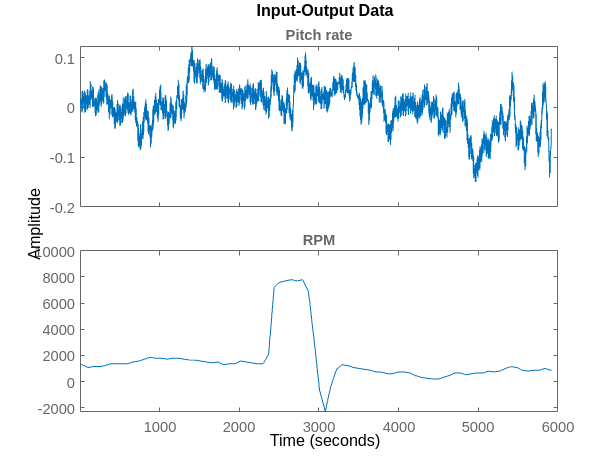

data = iddata(y,u);
set(data,'InputName',{'RPM'},'OutputName',{'Pitch rate'})
plot(data)

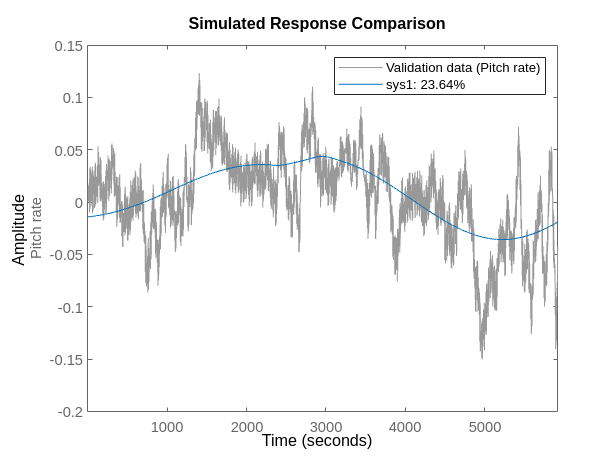

sys1= tfest(data,np,nz,iodelay);
compare(data,sys1)

### MIMO identification - Phugoid mode

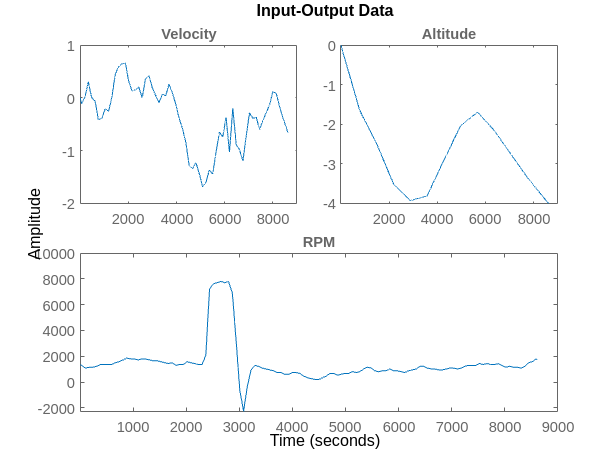

u = [u3];
y = [y1 y5];
np = [2;2];%[3 2; 3 3];
nz = [1;1];%[1 1; 2 2];
data = iddata(y,u);
set(data,'InputName',{'RPM'},'OutputName',{'Velocity', 'Altitude'});
plot(data)

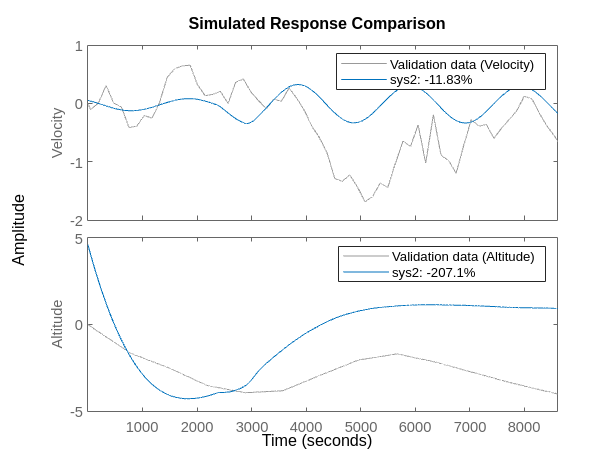

sys2= tfest(data,np,nz,iodelay);
compare(data,sys2)

### system identified

G2_tf = tf([sys1; sys2])  %Inputs-Throttle, evelator & outputs-Pitchrate, aoa, velocity, height

G2_tf =
 
  From input "RPM" to output...
                   3.498e-09 s + 1.154e-11
   Pitch rate:  -----------------------------
                s^2 + 7.324e-16 s + 1.754e-06
 
               -6.572e-08 s - 1.421e-10
   Velocity:  ---------------------------
              s^2 + 1.01e-14 s + 9.49e-06
 
                -2.604e-07 s + 4.103e-10
   Altitude:  ----------------------------
              s^2 + 0.001016 s + 5.411e-07
 
Continuous-time transfer function.



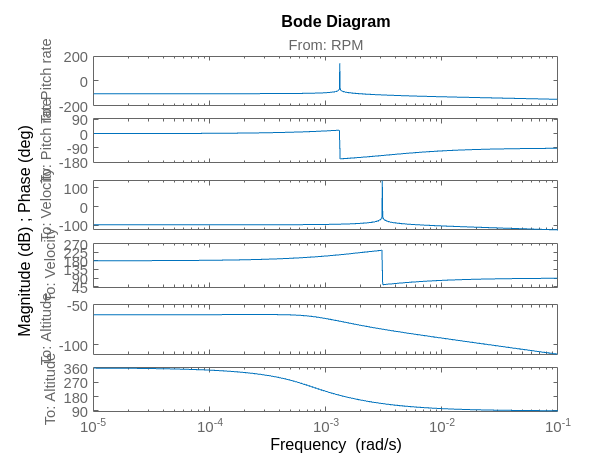

bode(G2_tf)

## System ID script - sine sweep

iodelay = 0;
u1 = rpm_s_sine;
u2 = elevator_s_sine;
u3 = rpm_p_sine;
u4 = elevator_p_sine;
airspeed_trim = vel_p_sine(1,1);
alt_trim = alt_p_sine(1,1);
pitch_rate_trim = q_s_sine(1,1);
alpha_trim = aoa_s_sine(1,1);
y1 = double(vel_p_sine - airspeed_trim);
y3 = q_s_sine - pitch_rate_trim;
y4 = double(aoa_s_sine - alpha_trim);
y5 = double(alt_p_sine - alt_trim);

### MIMO identification - short period mode

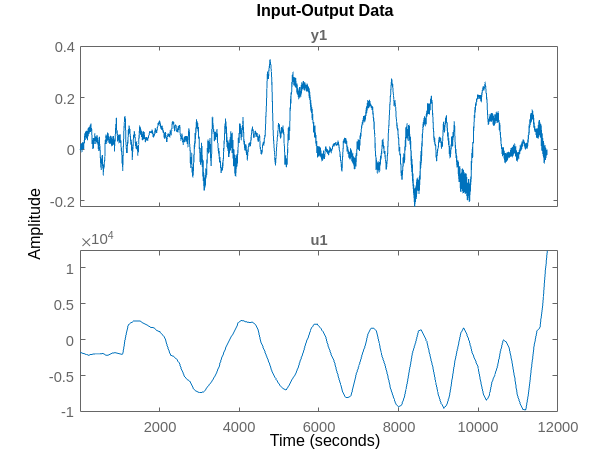

u = [u1];
y = [y3];
np = [2];%[2 2; 2 2];
nz = [1];%[1 2; 1 1];
data = iddata(y,u);
plot(data)

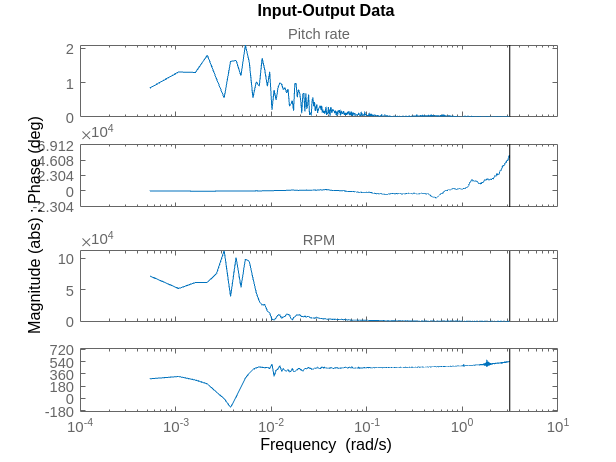

data = fft(data);
set(data,'InputName',{'RPM'},'OutputName',{'Pitch rate'})
plot(data)

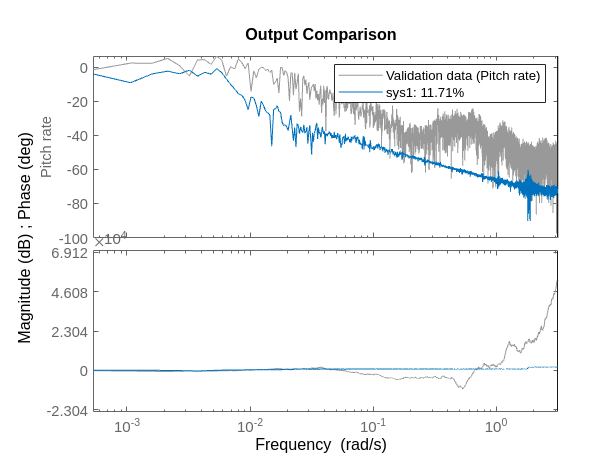

sys1= tfest(data,np,nz,iodelay);
compare(data,sys1)

### MIMO identification - Phugoid mode

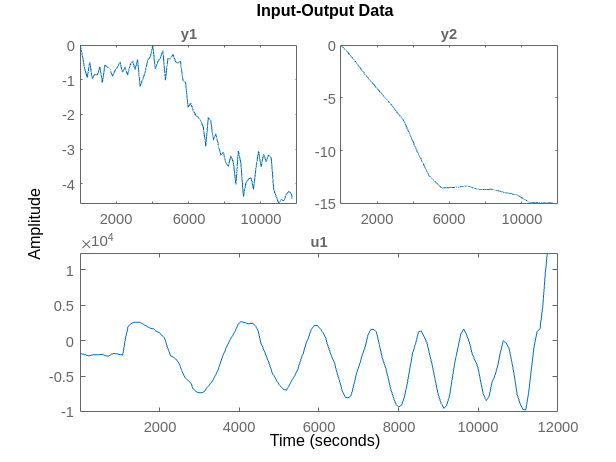

u = [u3];
y = [y1 y5];
np = [2;2];%[3 2; 3 3];
nz = [1;1];%[1 1; 2 2];
data = iddata(y,u);
plot(data)

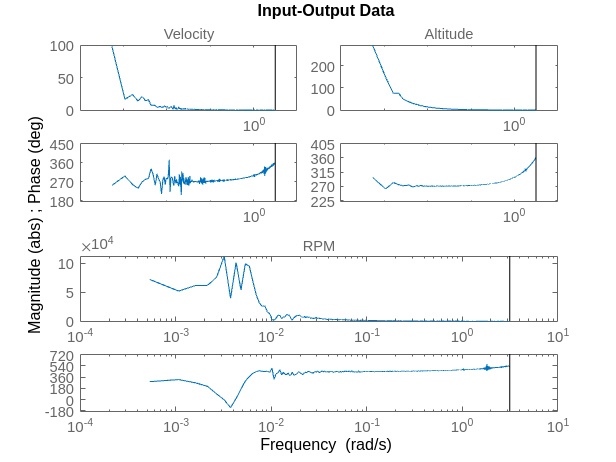

data = fft(data);
set(data,'InputName',{'RPM'},'OutputName',{'Velocity', 'Altitude'})
plot(data)

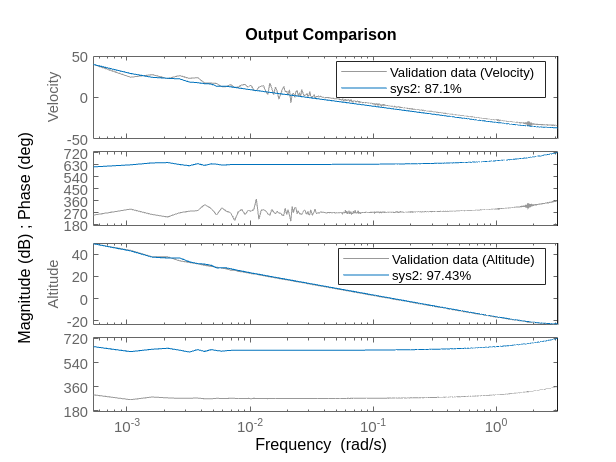

sys2= tfest(data,np,nz,iodelay);
compare(data,sys2)

### system identified

G3_tf = tf([sys1; sys2]) %Inputs-Throttle, evelator & outputs-Pitchrate, aoa, velocity, height

G3_tf =
 
  From input "RPM" to output...
                0.0003538 s - 1.86e-06
   Pitch rate:  ----------------------
                s^2 - 41.28 s + 0.2363
 
                -2.078e-08 s + 1.696e-10
   Velocity:  -----------------------------
              s^2 - 0.0001377 s + 2.699e-07
 
                -4.686e-08 s + 1.065e-09
   Altitude:  -----------------------------
              s^2 + 3.991e-05 s + 2.806e-07
 
Continuous-time transfer function.



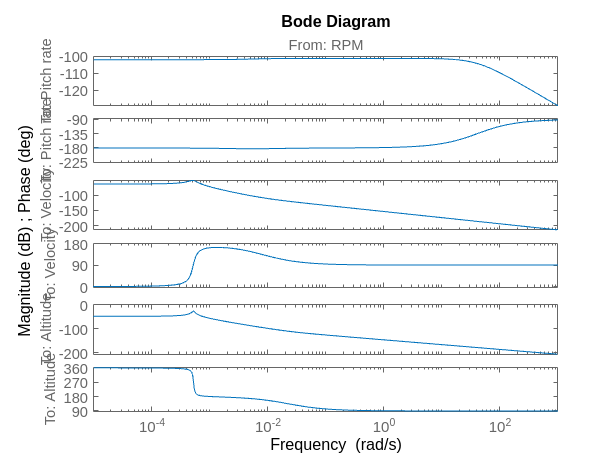

bode(G3_tf)